# **Particle Image Velocimetry**

The steps are the following:

- **Pre-processing:** image processing (improve visualization of images), calibration to get pixel-physical distance correlation

- **Mask creation:** hide obstacles and all disturbances (frame, regions with no particles, ...)

- **PIV algorithm:** cross correlation, fast fourier transform to get displacement of each particle that is then converted into velocity field

- **Post-processing:** clean-up the spurious vectors, and filter to get consistent data

- **Visualize results: **plot velocity, vorticy and all the required fields.

clear
close all
clc

% Initial settings
velocity = 12; % m/s
subdomain = 32; % 32x32 pxl
overlap = 50; % Overlapping 50%

## 1. Pre-processing

- Load the calibration images to get the correlation between pixel and real distance in mm

- Process the images to improve visualization

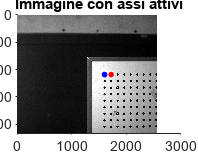

% Load calibration images
imgCalib = readB16("Calib\Cam2\Cam2_0001.b16");

% Convert and adjust visualization
imgCalib_normalized = mat2gray(imgCalib);
imgCalib_cont = imadjust(imgCalib_normalized);
% Appply filter
imgCalib_filtered = medfilt2(imgCalib_cont);

% Find circles to apply the calibration
[centers, radii] = imfindcircles(imgCalib_filtered, [20 500], 'ObjectPolarity', 'dark', 'Sensitivity', 0.9);

figure()
hold on
imshow(imgCalib_filtered)
viscircles(centers(5,:), radii(5), 'EdgeColor', 'b');
viscircles(centers(12,:), radii(12), 'EdgeColor', 'r');
axis on % Mostra gli assi (di default sono disattivati con imshow)
xlabel('Asse X (pixel)')
ylabel('Asse Y (pixel)')
title('Immagine con assi attivi')
hold off


% Spatial calibration
dist_real = 17.57; % in mm
dist_pix = sqrt((centers(5,1) - centers(12,1))^2 + (centers(5,2) - centers(12,2))^2);
magn = dist_pix/dist_real; % pixel/mm
fprintf('Magnification Factor: %f pxl/mm \n', magn)

Magnification Factor: 6.833487 pxl/mm 



% Temporal calibration (1/4 rule)
avg_displacement_pxl = 1/4 * subdomain;
avg_mean_displacement = avg_displacement_pxl/magn;
dt = avg_mean_displacement/velocity*1e-3 % s

dt = 9.7559e-05

## 2. Create a mask

- Create a mask to hide the obstacles to avoid problems when computing the particles displacements

%makeMask("mask");
mask = importdata('mask');

## 3. Start the cycle

We have 2 cameras which get 50 images each one at two different time-steps, therefore these will be the steps:

- Import i-th images from cam1 and cam2 of two consecutive time-steps

- Process images (improve visualization)

- Fuse the two image to reconstruct the scene and apply the mask

- Apply PIV algorithm

- Average the results

**NOTE:**

The process can be very HIGH computatinal demanding: the use of *Parallel Computing Toolbox* can improve significantly the time required (eventually half the computational time needed).

In this example we try to show what happens to just 1 couple of images.

%Load images
file1A = strcat("12ms\Cam1\Cam1_0001A.b16");
file1B = strcat("12ms\Cam1\Cam1_0001B.b16");
file2A = strcat("12ms\Cam2\Cam2_0001A.b16");
file2B = strcat("12ms\Cam2\Cam2_0001B.b16");

% Pre-processing
imag1A_filtered = filter_image(file1A, [0.001 0.05]);
imag1B_filtered = filter_image(file1B, [0.023 0.074]);
imag2A_filtered = filter_image(file2A, [0.01 0.45]);
imag2B_filtered = filter_image(file2B, [0.27 0.69]);

% Reconstruct the two images and apply mask
imgt1_filtered = [imag2A_filtered, imag1A_filtered];
imgt1_filtered(mask) = NaN;
imgt2_filtered = [imag2B_filtered, imag1B_filtered];
imgt2_filtered(mask) = NaN;

### **PIV Algorithm:**

- Divide each image into small, overlapping **interrogation windows**.

- Use **cross-correlation** to compare corresponding windows between two successive images.

- Identify the **peak of the correlation function** to find average particle displacement.

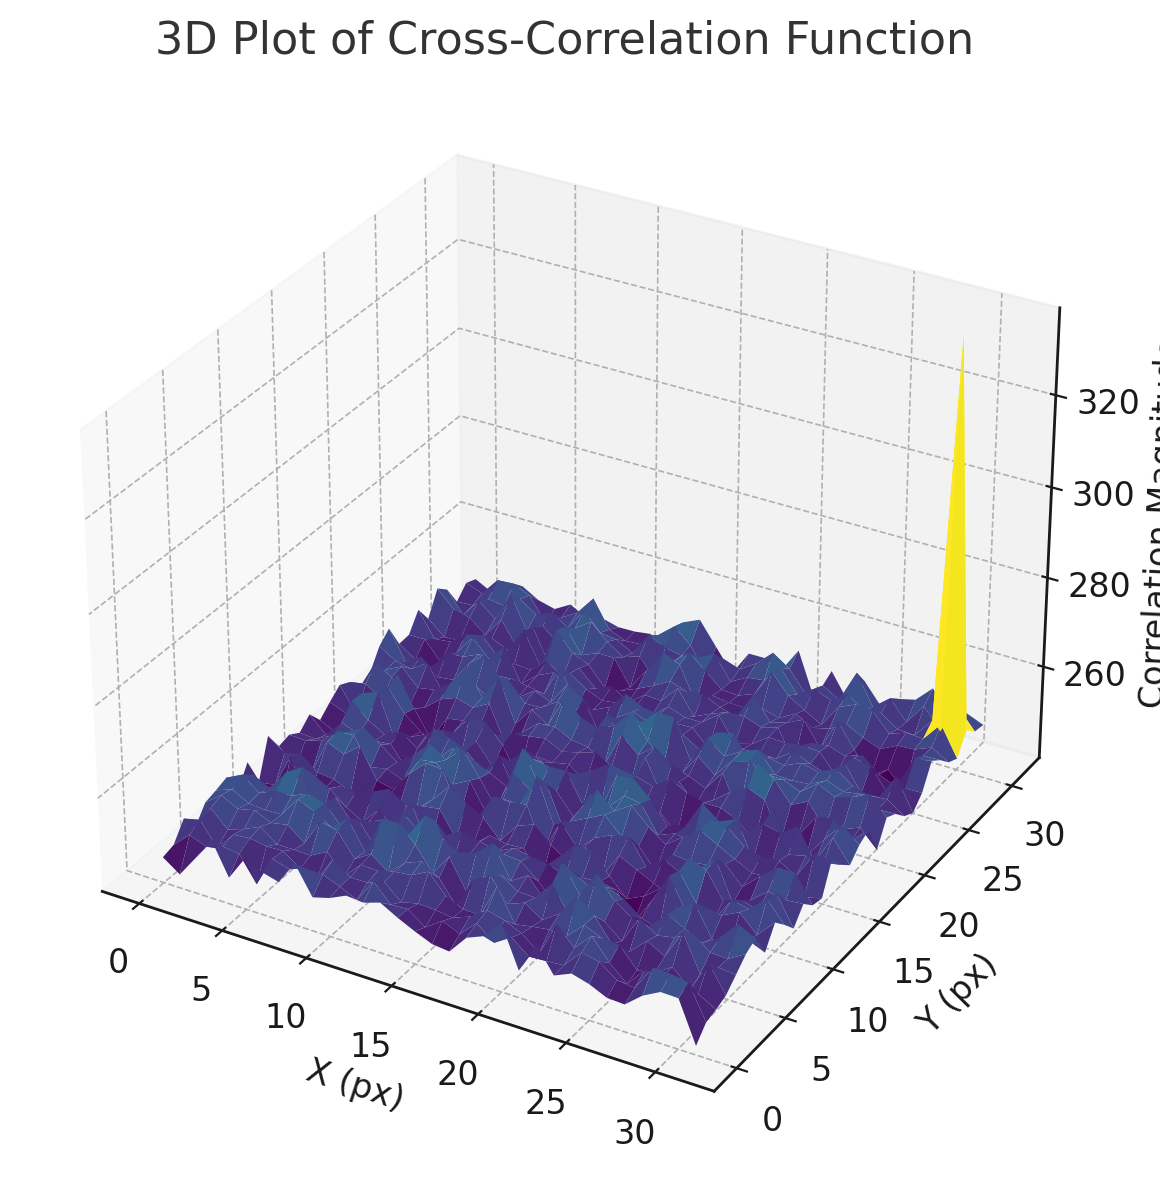

- Apply a **sub-pixel interpolation** to reduce the error:

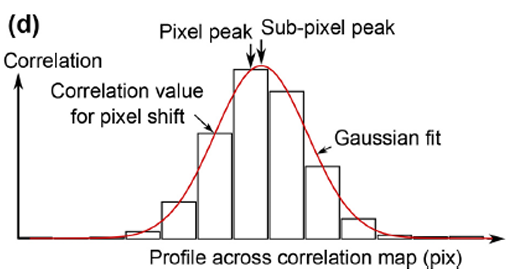

% Create a computational grid of the domain
[x_grid, y_grid] = meshgrid(1:overlap:(2*size(imgCalib_filtered, 2) - subdomain), ...
                            1:overlap:(size(imgCalib_filtered, 1) - subdomain)); 
% Initialize velocity Matrix
U = zeros(size(x_grid));
V = zeros(size(y_grid));

% Initialize variables for sub-pixel intep.
[X, Y] = meshgrid(-1:1, -1:1);
A = [X(:).^2, Y(:).^2, X(:).*Y(:), X(:), Y(:), ones(9, 1)];

% Extract windows for the entire grid from both images
for i = 1:(size(x_grid, 1))
    for j = 1:(size(x_grid,2))
        
        x_start = x_grid(i, j);
        y_start = y_grid(i, j);
        x_end = x_start + subdomain - 1;
        y_end = y_start + subdomain - 1;

        % Extract interrogation window at t
        window1 = imgt1_filtered(y_start:y_end, x_start:x_end);
        
        % Extract iterrogation window at t+dt
        window2 = imgt2_filtered(y_start:y_end, x_start:x_end);

        % Apply Fast Fourier Trasnsform
        F1 = fft2(window1);
        F2 = fft2(window2);
    
        % Compute the correlation
        C = real(ifft2(F1 .* conj(F2)));
        
        % Shift and find the correlation peak
        [maxval, max_idx] = max(C(:));
        [dy_sub, dx_sub] = ind2sub(size(C), max_idx);
    
        if isnan(maxval)
            dx_sub = 0;
            dy_sub = 0;
        end
         
        if dx_sub>subdomain/2
            dx_sub = dx_sub - subdomain;
        end
         
        if dy_sub>subdomain/2
            dy_sub = dy_sub - subdomain;
        end
    
        % Sub-pixel interpolation (parabolic)
        if dx_sub > 1 && dx_sub < size(C, 2) && dy_sub > 1 && dy_sub < size(C, 1)
    
            neighborhood = C(dy_sub-1:dy_sub+1, dx_sub-1:dx_sub+1);
            b = neighborhood(:);
            coeff = A\b;
            dx_sub1 = -coeff(4) / (2 * coeff(1));
            dy_sub1 = -coeff(5) / (2 * coeff(2));
            % Adjust w.r.t. global system
            dx_sub = dx_sub1 + dx_sub - 2;
            dy_sub = dy_sub1 + dy_sub - 2;  
    
        end
    
        U(i,j) = (dx_sub .* (1/magn).*1e-3) ./ dt; % m/s
        V(i,j) = (dy_sub .* (1/magn).*1e-3) ./ dt; % m/s
    end
end

### Vector validation

Now the results are "dirty":

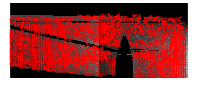

figure()
imshow(imgt1_filtered)
hold on
h = quiver(x_grid, y_grid, U, V, 'Color', 'r','AutoScaleFactor',3);
set(h, 'Color', 'r');
set(gca, 'YDir', 'reverse');
xlabel('X (pixel)')
ylabel('Y (pixel)')
hold off

So filters to remove spurious vectors must be applied.

- Apply **validation filters** to remove spurious vectors (e.g. global threshold, local median check).

- Remove outlayers (vector that are out of the frame)

- Remove noise (high velocity vectors, high velocity gradients)

% filtro gaussiano
U = imgaussfilt(U);
V = imgaussfilt(V);
U_filtered = medfilt2(U, [3 3]);  
V_filtered = medfilt2(V, [3 3]);  


%% Remove higher velocity vectors
[allU(:,:,1), allV(:,:,1), dU_dx, dV_dy] = vectorValidation(U_filtered, V_filtered);

Now the vector field is clean:

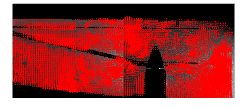

figure()
imshow(imgt1_filtered)
hold on
h = quiver(x_grid, y_grid, allU, allV, 'Color', 'r','AutoScaleFactor',3);
set(h, 'Color', 'r');
set(gca, 'YDir', 'reverse');
xlabel('X (pixel)')
ylabel('Y (pixel)')
hold off

## 6. Post - processing

Finally once we get the results of the velocity vector field we can visualize it with colormap, streamlines, ...

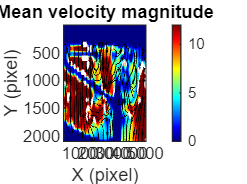

% Magnitude velocity
magnVelocity = sqrt(allU.^2 + allV.^2);

%Calcolo della vorticità
[du_dy, ~] = gradient(allU); % Derivate di u
[~, dv_dx] = gradient(allV); % Derivate di v
vorticity1 = dv_dx - du_dy; % Formula per la componente z della vorticità non filtered 
vorticity2 = dU_dx - dV_dy;% Formula per la componente z della vorticità filtered 

% Campo di veloictà
figure()
contourf(x_grid, y_grid, magnVelocity, 140, 'LineColor', 'none')
hold on
colormap(jet)
colorbar
clim([0 12])
h = streamslice(x_grid, y_grid, allU, allV); 
set(h, 'Color', 'k');
set(gca, 'YDir', 'reverse');
title('Mean velocity magnitude')
xlabel('X (pixel)')
ylabel('Y (pixel)')
hold off

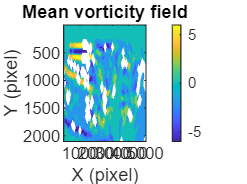


% Campo di vorticità
figure()
contourf(x_grid, y_grid, vorticity1, 'LineColor', 'none')
colorbar
colormap(parula)
clim([-6 6])
title('Mean vorticity field')
set(gca, 'YDir', 'reverse')
xlabel('X (pixel)')
ylabel('Y (pixel)')

**NOTE:**

To have good results we must repete this process for several couple of images and then average the results among all of them in that way you get results like these: